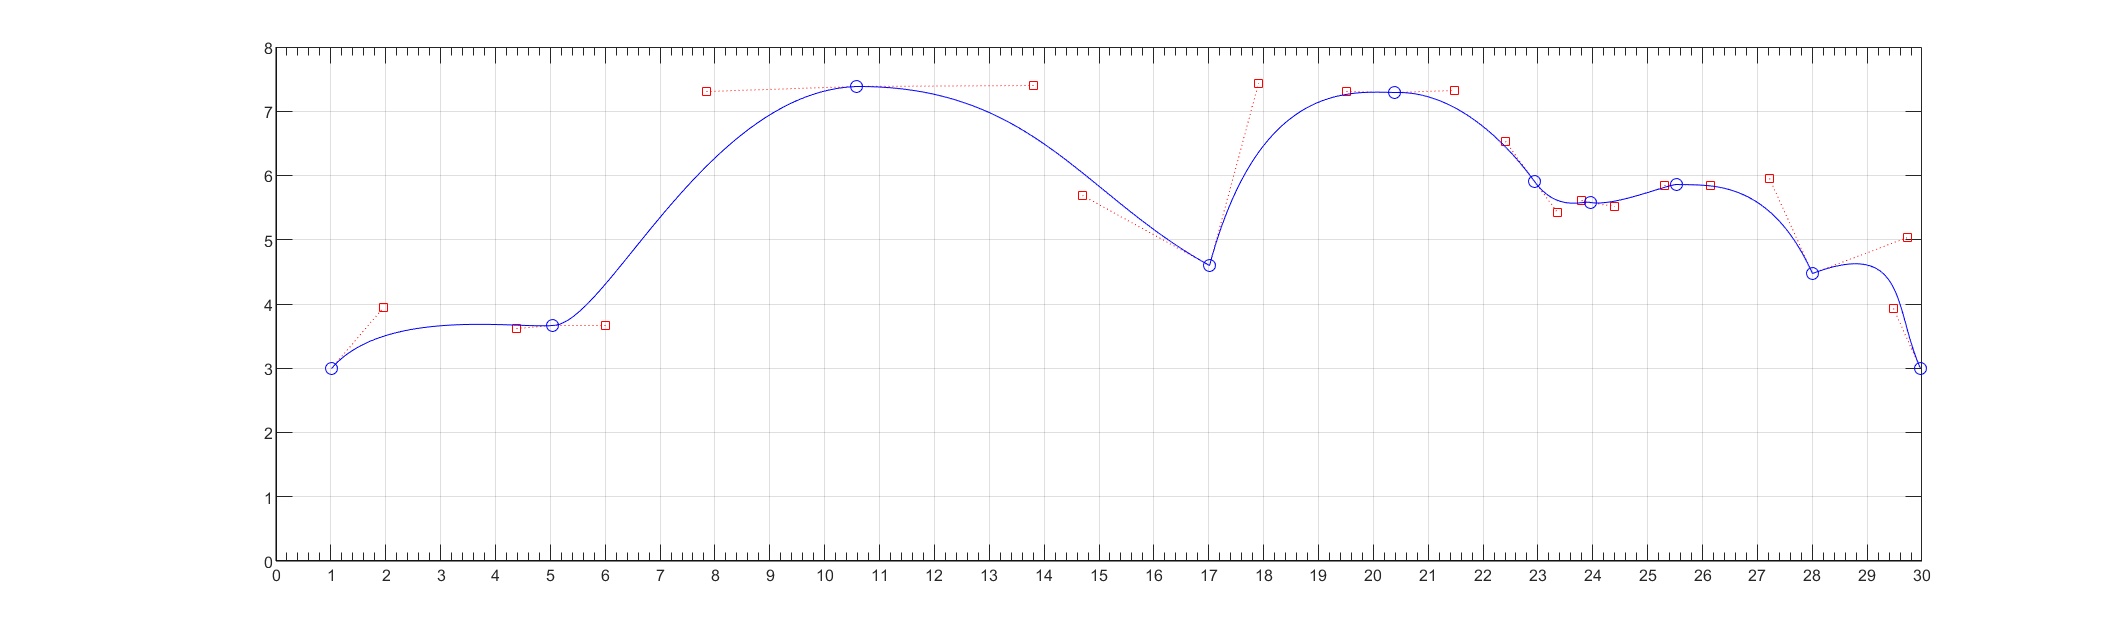

[A,B,v]=bezierdraw;%鼠标点击画出大致轮廓，并获取相关点坐标以及导数值数据

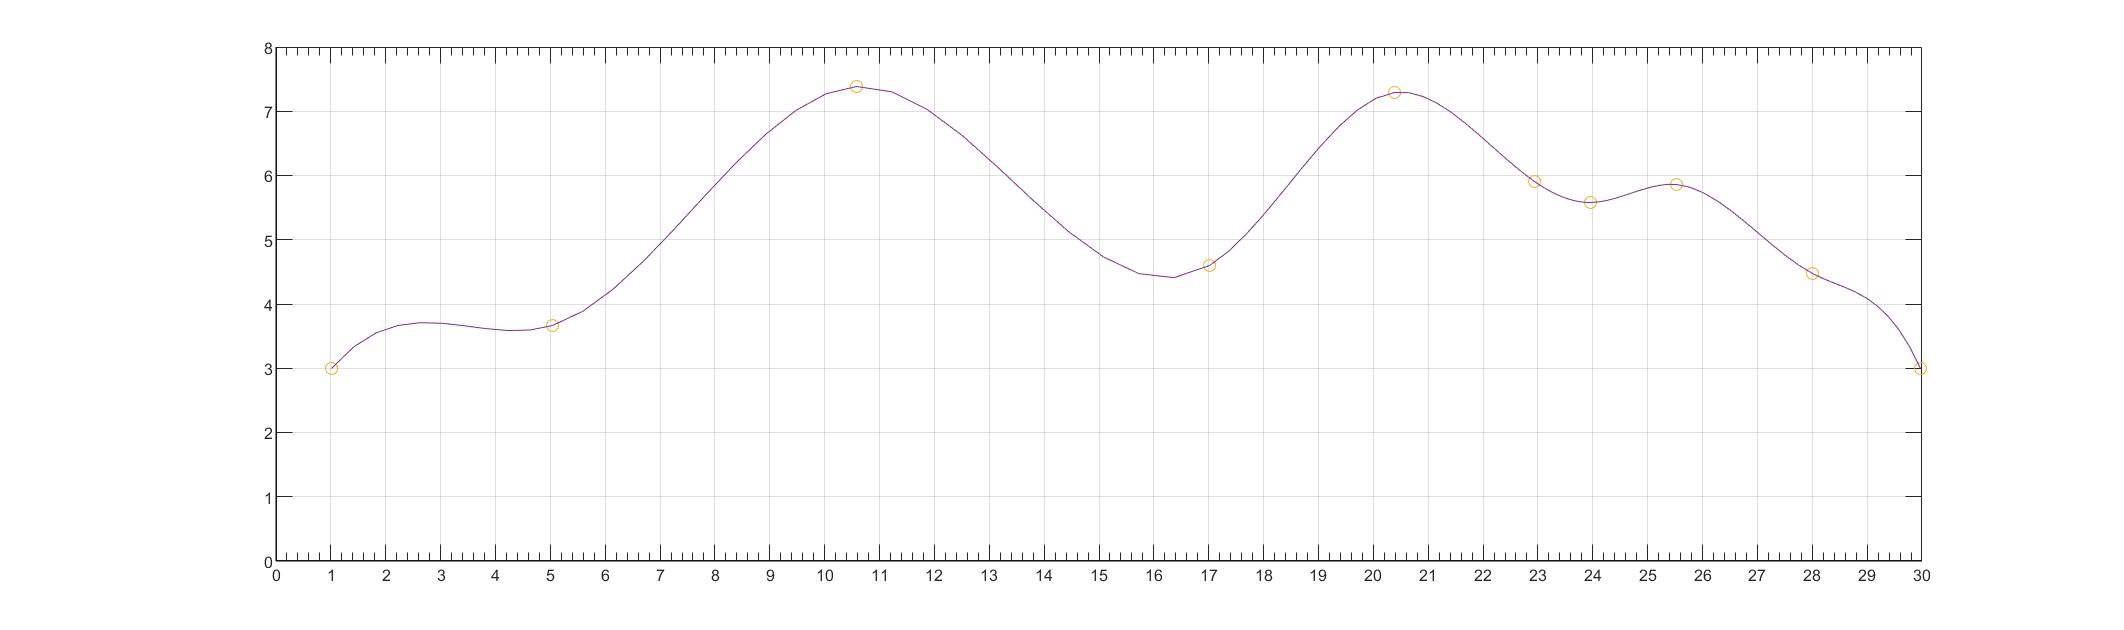

v=[v(1),v(length(v))];%获取曲线首末点导数值
splineplot(A',B',v,10);%画出相应三次样条插值

function [X,Y,k]=bezierdraw
%在MATLAB的图形窗口中点击得到第一个点
%然后再点击三次得到两个控制点和另外一个样条点
%然后继续以每次三次点击得到三个点，给曲线增加更多段
%按下回车终止程序
plot([0 30],[0,0],'k',[0 0],[0 8],'k');hold on
axis on;%设置坐标轴
set(gca,'fontsize',8,'xminortick','on');
set(gca,'XTick',0:1:30);
grid on;%设置坐标轴网格
t=0:.02:1;
[x,y]=ginput(1);%进行一次鼠标点击
X(1)=x;
Y(1)=y;%保存第一次首端点
k=[];
while(0 == 0)        
  [xnew,ynew] = ginput(3);  %另外三次点击
  if length(xnew) < 3 
    break                  %按下回车键，终止
  end
  x=[x;xnew];y=[y;ynew];%画出样条点和控制点pts
  k1=(y(2)-y(1))./(x(2)-x(1));
  k2=((y(4)-y(3))./(x(4)-x(3)));
  k=[k;k1;k2];%保存每次曲线首末端点导数值
  plot([x(1) x(2)],[y(1) y(2)],'r:',x(2),y(2),'rs');
  plot([x(3) x(4)],[y(3) y(4)],'r:',x(3),y(3),'rs');
  plot(x(1),y(1),'bo',x(4),y(4),'bo');
  bx=3*(x(2)-x(1)); by=3*(y(2)-y(1)); %样条方程
  cx=3*(x(3)-x(2))-bx;cy=3*(y(3)-y(2))-by;
  dx=x(4)-x(1)-bx-cx;dy=y(4)-y(1)-by-cy;
  xp=x(1)+t.*(bx+t.*(cx+t*dx));    %霍纳方法
  yp=y(1)+t.*(by+t.*(cy+t*dy));
  plot(xp,yp,'b')             %画出样条曲线
  x=x(4);y=y(4); %将上段最后一点转化为第一点，继续
  X=[X;x];Y=[Y;y];%保存每次曲线末端点
end
hold off
end
function coeff=splinecoeff(x,y,v)
n=length(x);
v1=v(1);
vn=v(2);
A=zeros(n,n);%矩阵A是n*n
r=zeros(n,1);
for i=1:n-1%定义deltas
    dx(i)=x(i+1)-x(i);dy(i)=y(i+1)-y(i);
end
for i=2:n-1%加载A矩阵
    A(i,i-1:i+1)=[dx(i-1),2*(dx(i-1)+dx(i)),dx(i)];
    r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1));%右侧端点
end
A(1,1:2)=[2*dx(1) dx(1)];r(1)=3*(dy(1)/dx(1)-v1);%钳制
A(n,n-1:n)=[dx(n-1),2*dx(n-1)];r(n)=3*(vn-dy(n-1)/dx(n-1));
coeff=zeros(n,3);
coeff(:,2)=A\r;%求解系数c
for i=1:n-1%求解b和d
    coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
    coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end

function [x1,y1]=splineplot(x,y,v,k)
n=length(x);
coeff=splinecoeff(x,y,v);
x1=[];y1=[];
for i=1:n-1
    xs=linspace(x(i),x(i+1),k+1);
    dx=xs-x(i);
    ys=coeff(i,3)*dx;%使用嵌套乘法
    ys=(ys+coeff(i,2)).*dx;
    ys=(ys+coeff(i,1)).*dx+y(i);
    x1=[x1;xs(1:k)'];y1=[y1;ys(1:k)'];
end
x1=[x1;x(end)];y1=[y1;y(end)];
plot([0 30],[0,0],'k',[0 0],[0 8],'k');hold on
axis on;%设置坐标轴
set(gca,'fontsize',8,'xminortick','on');
set(gca,'XTick',0:1:30);
grid on;%设置坐标轴网格
plot(x,y,'o',x1,y1)
end